**Project 1: Numerical simulation of a model neuron**

Tasks:

1. Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

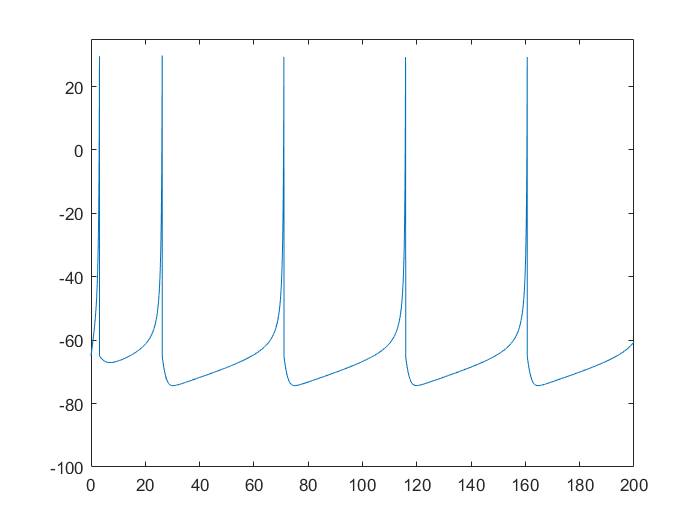

t=200;
dt=0.0025;

a=0.02;
b=0.2;
c=-65;
d=8;
I=10;
v0=c;
u0=b*v0;
f0=[v0,u0];
const=[a,b,c,d,I];

fun=@Izhikevich_Neuron_model;
add_func=@After_spike_reset;

[f]=RungeKutta(t,dt,f0,const,fun,add_func);
plot(f(:,1),f(:,2))
ylim([-100 35])

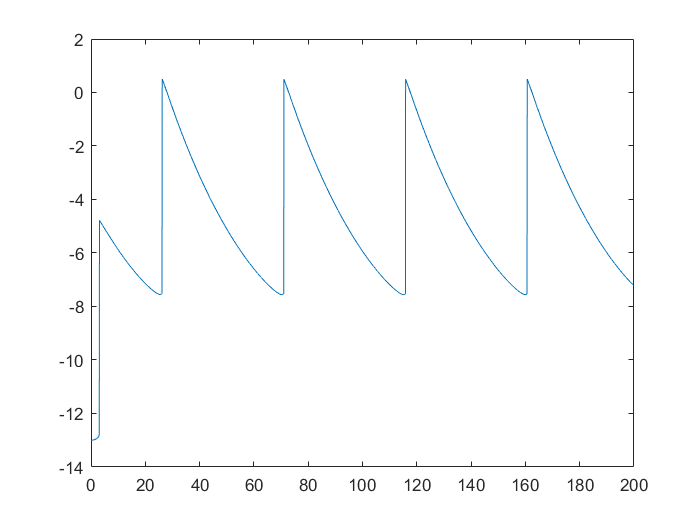

plot(f(:,1),f(:,3))

2. Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

3. Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

4. Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

5. Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.

function dfdt = Izhikevich_Neuron_model(t,f,const)
    a=const(1);
    b=const(2);
    if const(5)==0
        I=5*rand;
    else
        I=const(5); 
    end
    v=f(1);
    u=f(2);
    dv=0.04*v^2+5*v+140-u+I;
    du=a*(b*v-u);
    
    dfdt=[dv,du];
end

function f_after = After_spike_reset(t,f,const)
    c=const(3);
    d=const(4);
    v=f(1);
    u=f(2);
    if v>=30
        v=c;
        u=u+d;
    end
    f_after=[v,u];
end